clear
clc
close all

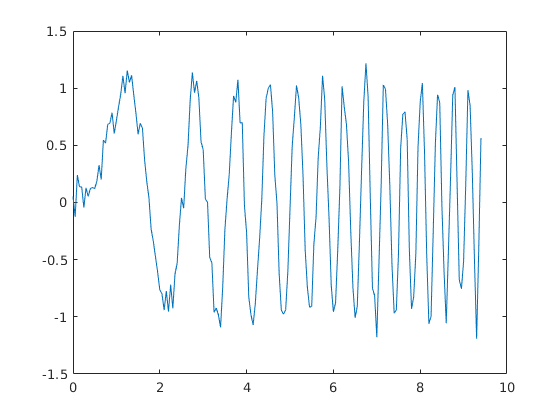

x = 0:0.05:3*pi; y = sin(x.^2); y = awgn(y,15,'measured');
p=con2seq(x); t=con2seq(y);
plot(x,y)


net1=feedforwardnet(50,'traingd');
net2=feedforwardnet(50,'traingda');
net3=feedforwardnet(50,'traincgf');
net4=feedforwardnet(50,'traincgp');
net5=feedforwardnet(50,'trainbfg');
net6=feedforwardnet(50,'trainlm');

net2.iw{1,1}=net1.iw{1,1};  %set the same weights and biases for the networks 
net2.lw{2,1}=net1.lw{2,1};
net3.iw{1,1}=net1.iw{1,1};  %set the same weights and biases for the networks 
net3.lw{2,1}=net1.lw{2,1};
net4.iw{1,1}=net1.iw{1,1};  %set the same weights and biases for the networks 
net4.lw{2,1}=net1.lw{2,1};
net5.iw{1,1}=net1.iw{1,1};  %set the same weights and biases for the networks 
net5.lw{2,1}=net1.lw{2,1};
net6.iw{1,1}=net1.iw{1,1};  %set the same weights and biases for the networks 
net6.lw{2,1}=net1.lw{2,1};

net2.b{1}=net1.b{1};
net2.b{2}=net1.b{2};
net3.b{1}=net1.b{1};
net3.b{2}=net1.b{2};
net4.b{1}=net1.b{1};
net4.b{2}=net1.b{2};
net5.b{1}=net1.b{1};
net5.b{2}=net1.b{2};
net6.b{1}=net1.b{1};
net6.b{2}=net1.b{2};


%training and simulation

%1 Epoch
net1.trainParam.epochs=1;  % set the number of epochs for the training 
net2.trainParam.epochs=1;
net3.trainParam.epochs=1;
net4.trainParam.epochs=1;
net5.trainParam.epochs=1;
net6.trainParam.epochs=1;

net1=train(net1,p,t);   % train the networks
net2=train(net2,p,t);
net3=train(net3,p,t);
net4=train(net4,p,t);
net5=train(net5,p,t);
net6=train(net6,p,t);

a11=sim(net1,p);     % simulate the networks with the input vector p
a21=sim(net2,p);
a31=sim(net3,p);
a41=sim(net4,p);
a51=sim(net5,p);
a61=sim(net6,p);

% 14 Epochs
net1.trainParam.epochs=14;
net2.trainParam.epochs=14;
net3.trainParam.epochs=14;
net4.trainParam.epochs=14;
net5.trainParam.epochs=14;
net6.trainParam.epochs=14;

net1=train(net1,p,t);
net2=train(net2,p,t);
net3=train(net3,p,t);
net4=train(net4,p,t);
net5=train(net5,p,t);
net6=train(net6,p,t);

a12=sim(net1,p);
a22=sim(net2,p);
a32=sim(net3,p);
a42=sim(net4,p);
a52=sim(net5,p);
a62=sim(net6,p);

% 985 Epochs
net1.trainParam.epochs=985;
net2.trainParam.epochs=985;
net3.trainParam.epochs=985;
net4.trainParam.epochs=985;
net5.trainParam.epochs=985;
net6.trainParam.epochs=985;

net1=train(net1,p,t);
net2=train(net2,p,t);
net3=train(net3,p,t);
net4=train(net4,p,t);
net5=train(net5,p,t);
net6=train(net6,p,t);

a13=sim(net1,p);
a23=sim(net2,p);
a33=sim(net3,p);
a43=sim(net4,p);
a53=sim(net5,p);
a63=sim(net6,p);

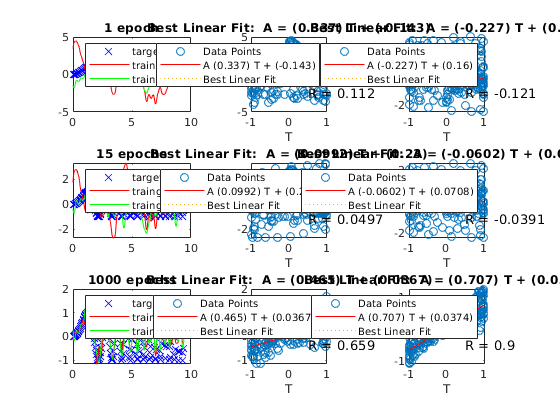

%plot traingd vs traingda
figure
subplot(3,3,1);
plot(x,y,'bx',x,cell2mat(a11),'r',x,cell2mat(a21),'g'); % plot the sine function and the output of the networks
title('1 epoch');
legend('target','traingd','traingda','Location','north');
subplot(3,3,2);
postregm(cell2mat(a11),y); % perform a linear regression analysis and plot the result
subplot(3,3,3);
postregm(cell2mat(a21),y);
%
subplot(3,3,4);
plot(x,y,'bx',x,cell2mat(a12),'r',x,cell2mat(a22),'g');
title('15 epochs');
legend('target','traingd','traingda','Location','north');
subplot(3,3,5);
postregm(cell2mat(a12),y);
subplot(3,3,6);
postregm(cell2mat(a22),y);
%
subplot(3,3,7);
plot(x,y,'bx',x,cell2mat(a13),'r',x,cell2mat(a23),'g');
title('1000 epochs');
legend('target','traingd','traingda','Location','north');
subplot(3,3,8);
postregm(cell2mat(a13),y);
subplot(3,3,9);
postregm(cell2mat(a23),y);

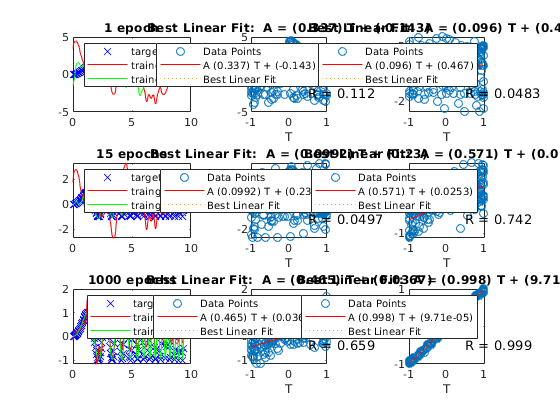

%plot traingd vs traincgf
figure
subplot(3,3,1);
plot(x,y,'bx',x,cell2mat(a11),'r',x,cell2mat(a31),'g'); % plot the sine function and the output of the networks
title('1 epoch');
legend('target','traingd','traingcgf','Location','north');
subplot(3,3,2);
postregm(cell2mat(a11),y); % perform a linear regression analysis and plot the result
subplot(3,3,3);
postregm(cell2mat(a31),y);
%
subplot(3,3,4);
plot(x,y,'bx',x,cell2mat(a12),'r',x,cell2mat(a32),'g');
title('15 epochs');
legend('target','traingd','traingcgf','Location','north');
subplot(3,3,5);
postregm(cell2mat(a12),y);
subplot(3,3,6);
postregm(cell2mat(a32),y);
%
subplot(3,3,7);
plot(x,y,'bx',x,cell2mat(a13),'r',x,cell2mat(a33),'g');
title('1000 epochs');
legend('target','traingd','traincgf','Location','north');
subplot(3,3,8);
postregm(cell2mat(a13),y);
subplot(3,3,9);
postregm(cell2mat(a33),y);

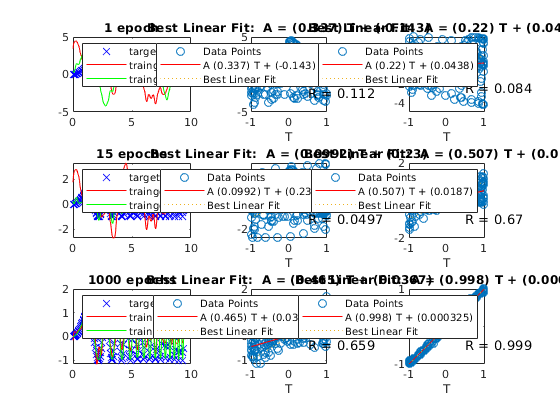

%plot traingd vs traingcgp
figure
subplot(3,3,1);
plot(x,y,'bx',x,cell2mat(a11),'r',x,cell2mat(a41),'g'); % plot the sine function and the output of the networks
title('1 epoch');
legend('target','traingd','traingcgp','Location','north');
subplot(3,3,2);
postregm(cell2mat(a11),y); % perform a linear regression analysis and plot the result
subplot(3,3,3);
postregm(cell2mat(a41),y);
%
subplot(3,3,4);
plot(x,y,'bx',x,cell2mat(a12),'r',x,cell2mat(a42),'g');
title('15 epochs');
legend('target','traingd','traingcgp','Location','north');
subplot(3,3,5);
postregm(cell2mat(a12),y);
subplot(3,3,6);
postregm(cell2mat(a42),y);
%
subplot(3,3,7);
plot(x,y,'bx',x,cell2mat(a13),'r',x,cell2mat(a43),'g');
title('1000 epochs');
legend('target','traingd','traingcgp','Location','north');
subplot(3,3,8);
postregm(cell2mat(a13),y);
subplot(3,3,9);
postregm(cell2mat(a43),y);

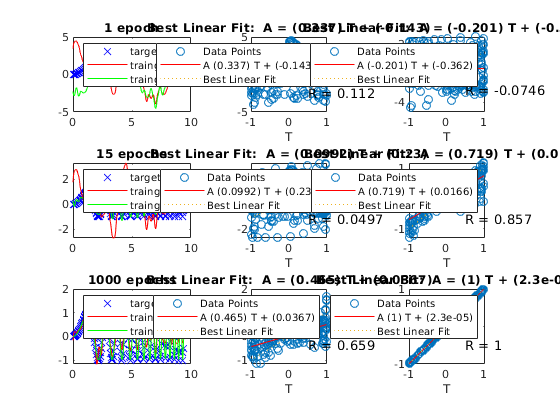

%plot traingd vs traingbfg
figure
subplot(3,3,1);
plot(x,y,'bx',x,cell2mat(a11),'r',x,cell2mat(a51),'g'); % plot the sine function and the output of the networks
title('1 epoch');
legend('target','traingd','traingbfg','Location','north');
subplot(3,3,2);
postregm(cell2mat(a11),y); % perform a linear regression analysis and plot the result
subplot(3,3,3);
postregm(cell2mat(a51),y);
%
subplot(3,3,4);
plot(x,y,'bx',x,cell2mat(a12),'r',x,cell2mat(a52),'g');
title('15 epochs');
legend('target','traingd','traingbfg','Location','north');
subplot(3,3,5);
postregm(cell2mat(a12),y);
subplot(3,3,6);
postregm(cell2mat(a52),y);
%
subplot(3,3,7);
plot(x,y,'bx',x,cell2mat(a13),'r',x,cell2mat(a53),'g');
title('1000 epochs');
legend('target','traingd','traingbfg','Location','north');
subplot(3,3,8);
postregm(cell2mat(a13),y);
subplot(3,3,9);
postregm(cell2mat(a53),y);

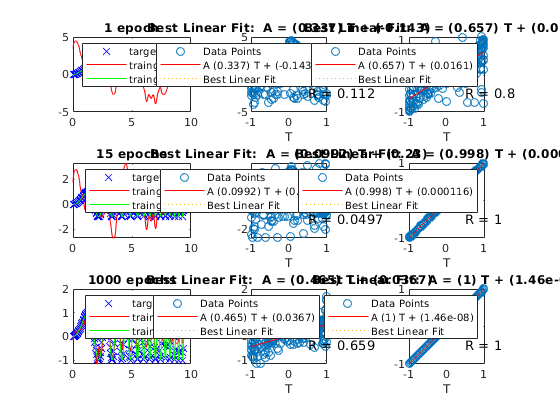

%plot traingd vs trainlm
figure
subplot(3,3,1);
plot(x,y,'bx',x,cell2mat(a11),'r',x,cell2mat(a61),'g'); % plot the sine function and the output of the networks
title('1 epoch');
legend('target','traingd','traingclm','Location','north');
subplot(3,3,2);
postregm(cell2mat(a11),y); % perform a linear regression analysis and plot the result
subplot(3,3,3);
postregm(cell2mat(a61),y);
%
subplot(3,3,4);
plot(x,y,'bx',x,cell2mat(a12),'r',x,cell2mat(a62),'g');
title('15 epochs');
legend('target','traingd','trainglm','Location','north');
subplot(3,3,5);
postregm(cell2mat(a12),y);
subplot(3,3,6);
postregm(cell2mat(a62),y);
%
subplot(3,3,7);
plot(x,y,'bx',x,cell2mat(a13),'r',x,cell2mat(a63),'g');
title('1000 epochs');
legend('target','traingd','trainglm','Location','north');
subplot(3,3,8);
postregm(cell2mat(a13),y);
subplot(3,3,9);
postregm(cell2mat(a63),y);

Personal Regression Example: Student Number = 0773125

Six Largest Digits = 77532

Ts = [T1 T2 T3 T4 T5];
nums = [7; 7; 5; 3; 2];
Tnew = sum(Ts*nums,2)/(sum(nums));
dataset = [X1 X2 Tnew];

full_set = datasample(dataset,3000,1, 'Replace', false);
train_set = full_set(1:1000,:);
test_set = full_set(1001:2000,:);
val_set = full_set(2001:3000,:);

Define your datasets: your dataset consists now of X1, X2 and T new. Draw 3 (independent) samples of 1 000 points each. Use them as the training set, validation set, and test set, respectively. Motivate the choice of the datasets. Plot the surface of your training set using the Matlab functions scatteredInterpolant, plot3 and mesh.

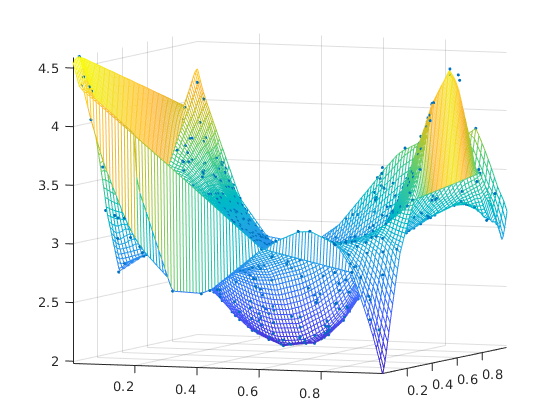

x = train_set(:,1);
y = train_set(:,2);
z = train_set(:,3);

xlin = linspace(min(x), max(x));
ylin = linspace(min(y), max(y));

[X,Y] = meshgrid(xlin,ylin);

f = scatteredInterpolant(x,y,z);
Z = f(X,Y);

figure
mesh(X,Y,Z)
axis tight; hold on
plot3(x,y,z,'.');

Build and train your feedforward Neural Network: use the training and validation sets. Build the ANN with 2 inputs and 1 output. Select a suitable model for the problem (number of hidden layers, number of neurons on each hidden layer). Select the learning algorithm and the transfer function that may work best for this problem. Motivate your decisions. When you try different networks, clearly say at the end which one you would select as the best for this problem and why.